%hongtao xu; 260773785
T = 10;
dt = 0.1;
t = 0:dt:T;

y1 = zeros(size(t));
y1(t<10) = t(t<10);

y2 = zeros(size(t));
y2(t<5) = 0;
y2(t>=5)= -1;

y3(t>=0)=0.1*t(t>=0);
y4(t>=0)=exp(-t/10);


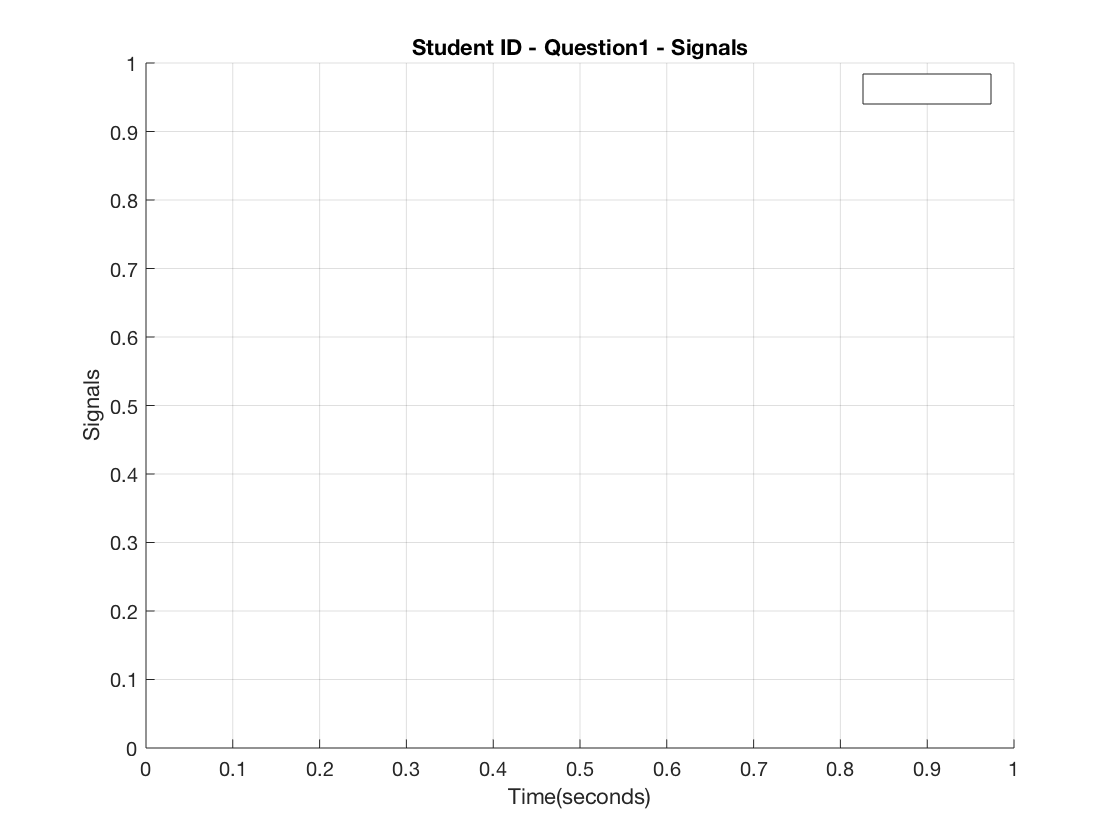

figure;
hold on 
%fill in my plotes command

title(sprintf('Student ID - Question1 - Signals'));
xlabel('Time(seconds)')
ylabel('Signals')
grid on; 
legend('y_1(t)','y_2(t)','y_3(t)','y_4(t)','location','best')

clc
syms t s

f1 = dirac(t);
f2 = sqrt(t) + 4*t + 1;
f3 = t.*exp(-t) + exp(-t).*0.5 + exp(-3*t); %.* is times 
f4 = sin(2*t) + cos(t).^2;
f5 = exp(-t).*sin(5*t+pi/3)+(t.^2).*exp(-2*t);

F1 = laplace(f1, t, s);
F2 = laplace(f2, t, s);
F3 = laplace(f3, t, s);
F4 = laplace(f4, t, s);
F5 = laplace(f5, t, s);
F3 = simplify (1/(2*(s + 1)) + 1/(s + 1)^2 + 1/(s + 3));
F4 = simplify (2/(s^2 + 4) + (s^2 + 2)/(s*(s^2 + 4)));
F5 = simplify (2/(s + 2)^3 + 5/(2*((s + 1)^2 + 25)) + (3^(1/2)*(s + 1))/(2*((s + 1)^2 + 25)));

G1(s) = 1/s; 
G2(s) = 1/(s.*(s+1));
G3(s) = 5/(s^2+25);
G4(s) = (10*s+1)/(s^2+2*s+10);
G5(s) = (2*(s+1)*(s^2+4)/((s^2+4*s+1)*(s^2+9)));

g1=ilaplace(G1,s,t);
g2=ilaplace(G2,s,t);
g3=ilaplace(G3,s,t);
g4=ilaplace(G4,s,t);
g5=ilaplace(G5,s,t);